# Parameter Identification of Double Pendulum

This example script will help users to identify the parameters of triple pendulum arm. We define pars=[m1 m2 m3 a1 a2 a3 L1 L2 I1 I2 I3 k1 k2 k3 g] (our optimization parameters), where a1,2,3 (m) is the position of the mass center of double pendulum arm, m1,2,3 (kg) is the mass of pendulum arm, I1,2,3 (kg*m^2)is the moment of inertia of pendulum arm, k1,2,3 is the unitless friction coefficient, g (m/s^2) is the gravitational acceleration of earth. All units are: m-kg standard.

## Import the Measurement Data

In this section, we will import the Data we measured from the single pendulum experimental set-up.

clc;clear all;close all
% First load data
load('TriplePendulumDataForParameterEstimation.mat');

**Place the **`x0`** value and any other problem data into the workspace** by running this section before proceeding.

## Now Determine the Optimization Parameter's Initial Value

% Now set up the initial estimated parameters, note that EstimationParameters=[m1 m2 m3 a1 a2 a3 L1 L2 I1 I2 I3 k1 k2 k3 g];
% The units are: m-kg standard
EstimationParameters0=[0.135 0.135 0.1 0.0939 0.1270 0.12 0.1727 0.2286 0.0017 0.0026 0.002 0.0003 0.0001 0.0001 9.8080];

% Set up the upper bound and lower bound of the parameters
lb=[0.08 0.08 0.08  0.0939 0.1157  0.1  0.1726  0.2285 1e-4 1e-4 1e-4 1e-5 1e-5 1e-5 9.808];
up=[0.3  0.3  0.3   0.16   0.2286  0.22 0.1728  0.2287 0.1  0.1  0.1  0.1  0.1  0.1  9.809];

% Now determine the number of optimization parameter
NumOfVars=length(EstimationParameters0);

% Determine the number of optimization parameter, if it is 9, then set the g=9.8083 as defaults
if length(EstimationParameters0)==14
    g=9.8083;
end

## Perform the Parameter Optimization

Please choose the objective function as "ObjectiveFuntion_DoublePendulumParameterEstimation", optimization input as "EstimationParameters", fixed input as Y_id.

Run the task by clicking the striped bar to the left, or by choosing **Run** or **Section > Run Section**, or by pressing `Control+Enter`.

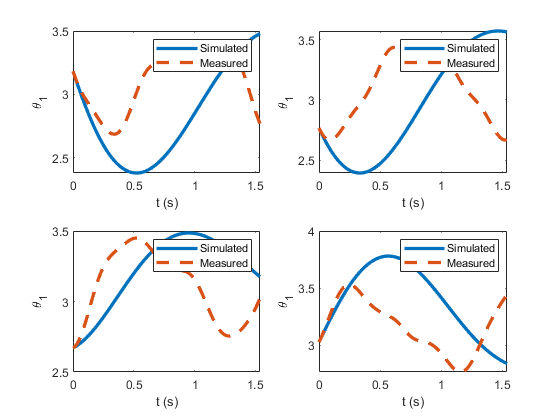

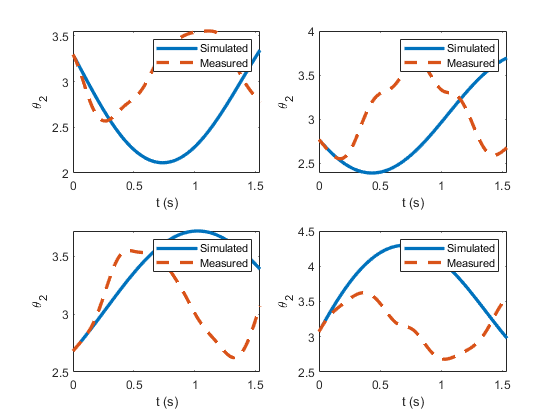

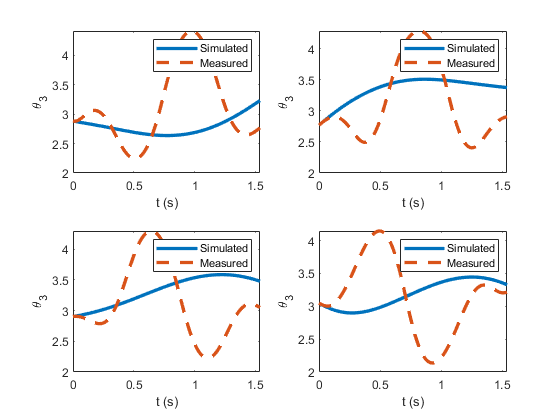


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0             100       2.086e+05       4.342e+05        0
    1             200       1.123e+05       3.815e+05        0
    2             300       2.868e+04       2.736e+05        0
    3             400        1.62e+04       2.057e+05        0
    4             500        1.62e+04       1.821e+05        1
    5             600       1.134e+04        1.46e+05        0
    6             700       1.134e+04       1.666e+05        1
    7             800       1.085e+04       1.489e+05        0
    8             900       1.085e+04       1.257e+05        1
    9            1000       1.085e+04       1.019e+05        2
   10            1100        1.03e+04       8.495e+04        0
   11            1200            7658        8.16e+04        0
   12            1300            7014           1e+05        0
   13            1400            6991       9.65

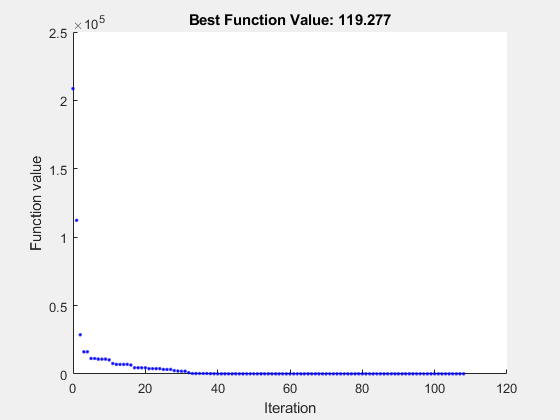

% Pass fixed parameters to objfun
objfun = @(EstimationParameters)ObjectiveFuntion_TriplePendulumParameterEstimation(EstimationParameters,...
    dt,Y_id);

% Set nondefault solver options
options = optimoptions("particleswarm","UseParallel",true,"Display","iter",...
    "PlotFcn","pswplotbestf");

% Solve
[EstimatedParameters,l2normError] = particleswarm(objfun,NumOfVars,lb,up,options);


% Clear variables
clearvars objfun options

## Results

`We will save the parameter estimation result "EstimatedParameters" into a mat file called "EstimatedParameters.mat"`

EstimatedParameters

EstimatedParameters =     0.2582    0.2794    0.1186    0.1600    0.2029    0.1837    0.1728    0.2287    0.0001    0.0003    0.0002    0.0015    0.0003    0.0000    9.8083


if length(EstimationParameters0)==14
    EstimatedParameters=[EstimatedParameters g];
end
save('EstimatedParameters_TriplePendulum.mat','EstimatedParameters');

## Now, Validate the Estimated Parameters Using Validation Data

Y_es=cell(length(Y_id),1);

for i=1:length(Y_id)
    % First determine the simulation time
    tspan=0:dt:length(Y_id{1})*dt-dt;
    
    % Next, determine the initial condition used for simulation, the first
    % data will be used as initial condition
    y0=Y_id{i}(:,1);
    
    % Now, run the simulation and simulate the system
    if length(EstimationParameters0)==15
        [~,y_es]=ode89(@(t,y)TriplePendulumODE_Mounted(t,y,EstimatedParameters(1),EstimatedParameters(2),EstimatedParameters(3),...
            EstimatedParameters(4),EstimatedParameters(5),EstimatedParameters(6),...
            EstimatedParameters(7),EstimatedParameters(8),...
            EstimatedParameters(9),EstimatedParameters(10),EstimatedParameters(11),...
            EstimatedParameters(12),EstimatedParameters(13),EstimatedParameters(14),...
            EstimatedParameters(15)),tspan,y0);
    else
        [~,y_es]=ode89(@(t,y)TriplePendulumODE_Mounted(t,y,EstimatedParameters(1),EstimatedParameters(2),EstimatedParameters(3),...
            EstimatedParameters(4),EstimatedParameters(5),EstimatedParameters(6),...
            EstimatedParameters(7),EstimatedParameters(8),...
            EstimatedParameters(9),EstimatedParameters(10),EstimatedParameters(11),...
            EstimatedParameters(12),EstimatedParameters(13),EstimatedParameters(14),...
            9.8083),tspan,y0);
    end
    
    % Now store the simulated data into an array
    Y_es{i}=y_es';
    
    % Now calculate the difference (l2 norm) of the simualted data and measrued data
    if i==1
        l2normError=norm(Y_id{i}-Y_es{i})^2;
    else
        l2normError=l2normError+norm(Y_id{i}-Y_es{i})^2;
    end
end


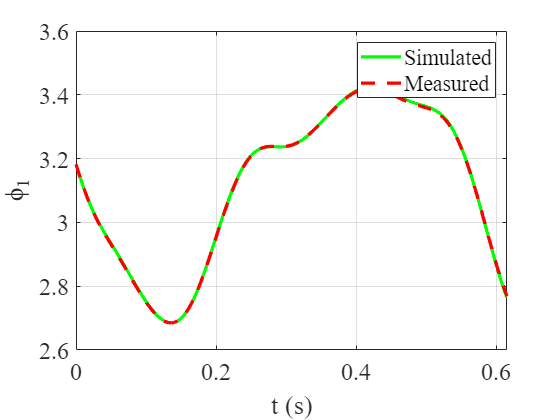

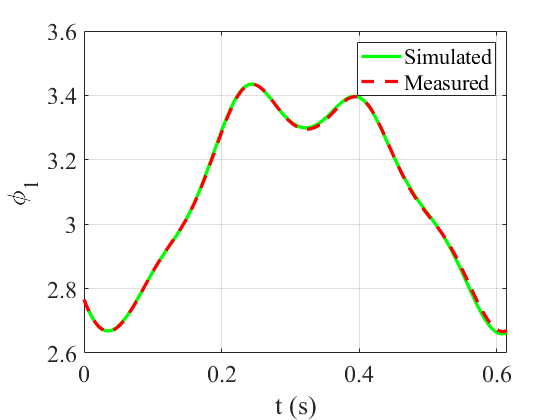

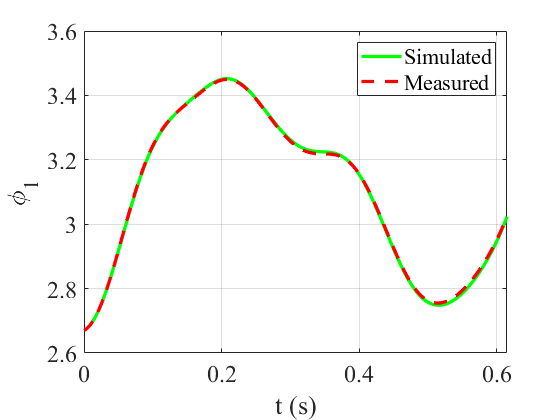

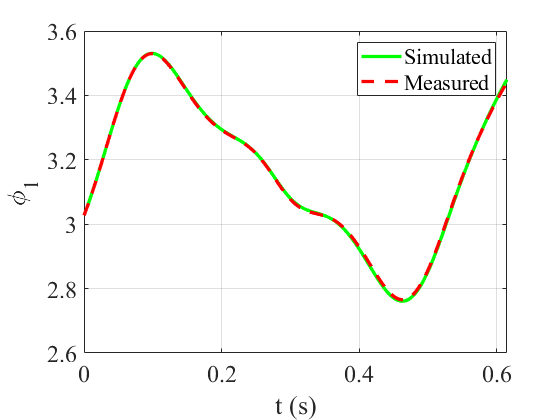

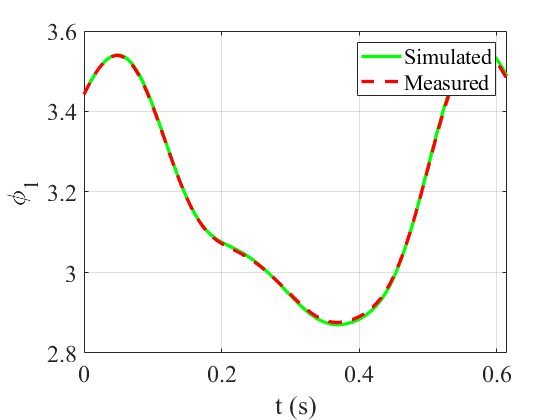

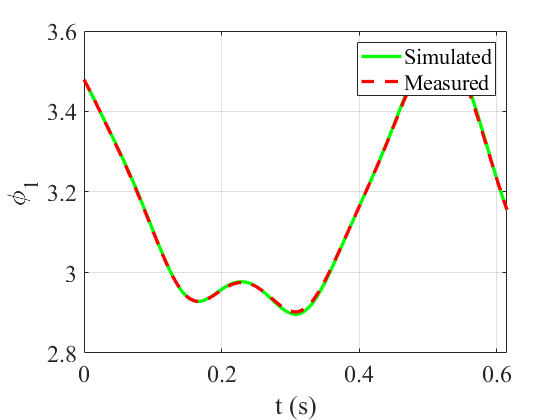

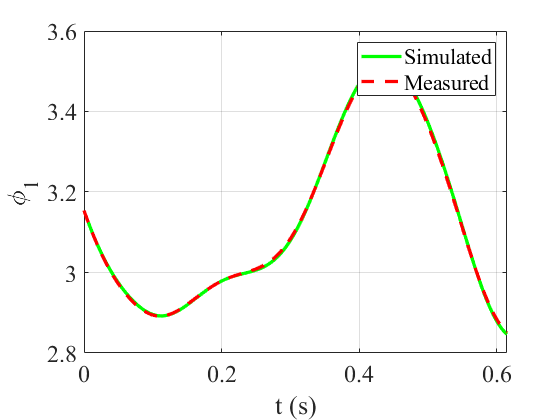

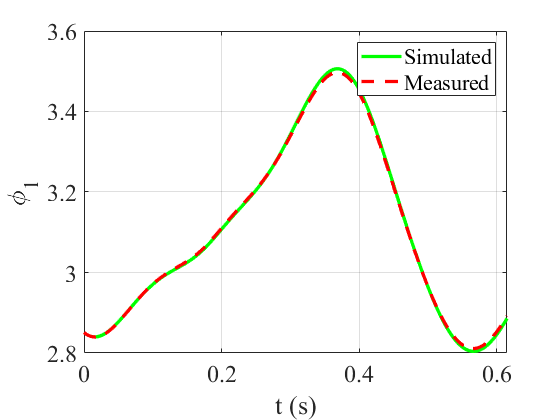

close all
for i=1:length(Y_id)
    figure(i)
    plot(0:dt:length(Y_id{i})*dt-dt,Y_es{i}(1,:),'LineWidth',2.5,'color','green')
    hold on
    plot(0:dt:length(Y_id{i})*dt-dt,Y_id{i}(1,:),'LineWidth',2.5,'LineStyle','--','color','red')
    legend("Simulated","Measured")
    xlabel("t (s)")
    ylabel("\phi_1")
    a = get(gca,'XTickLabel');
    set(gca,'XTickLabel',a,'FontName','Times','fontsize',18)
    grid on
end

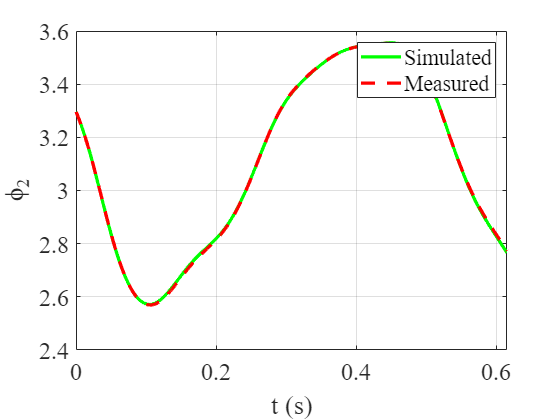

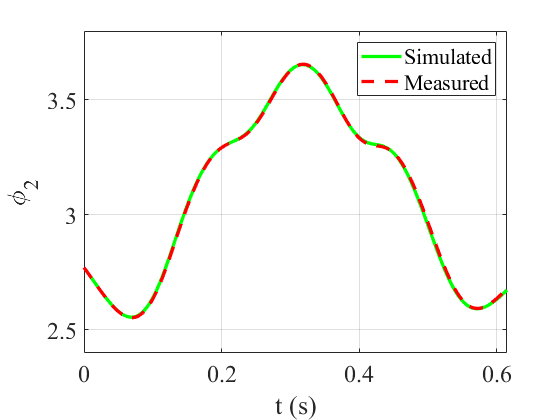

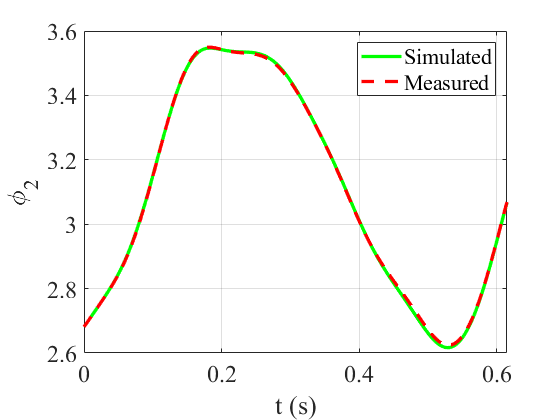

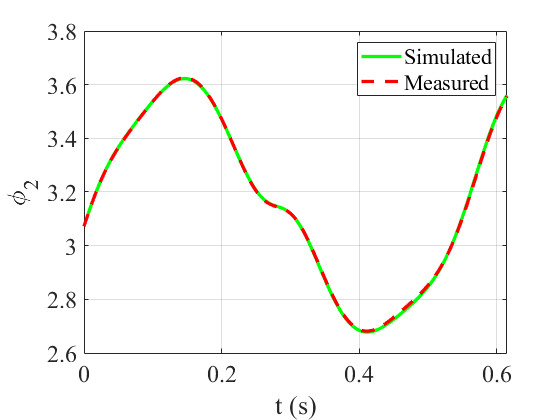

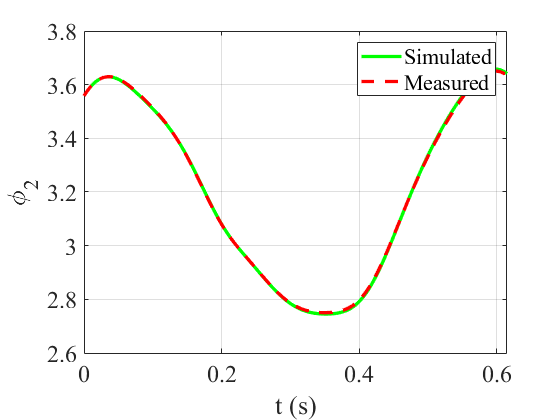

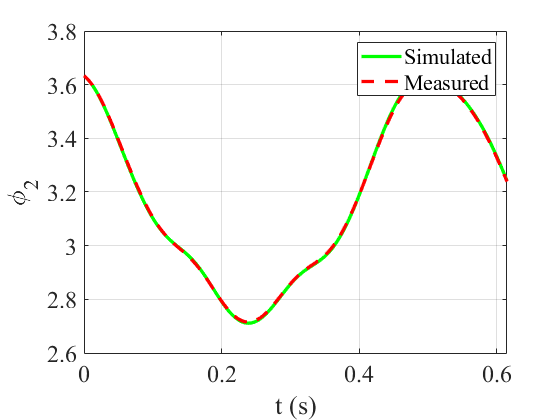

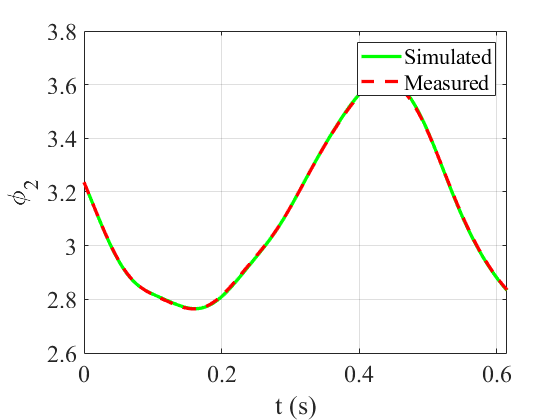

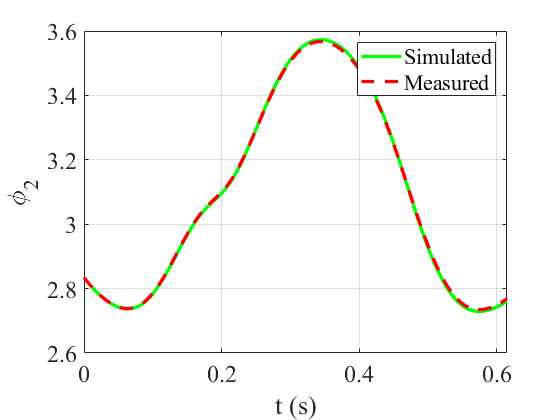

for i=1:length(Y_id)
    figure(length(Y_id)+i)
    plot(0:dt:length(Y_id{i})*dt-dt,Y_es{i}(2,:),'LineWidth',2.5,'color','green')
    hold on
    plot(0:dt:length(Y_id{i})*dt-dt,Y_id{i}(2,:),'LineWidth',2.5,'LineStyle','--','color','red')
    legend("Simulated","Measured")
    xlabel("t (s)")
    ylabel("\phi_2")
    a = get(gca,'XTickLabel');
    set(gca,'XTickLabel',a,'FontName','Times','fontsize',18)
    grid on
end

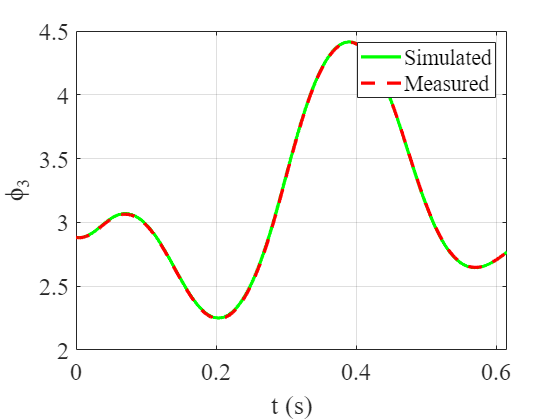

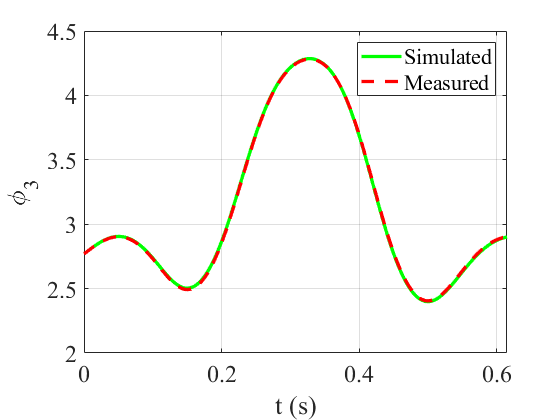

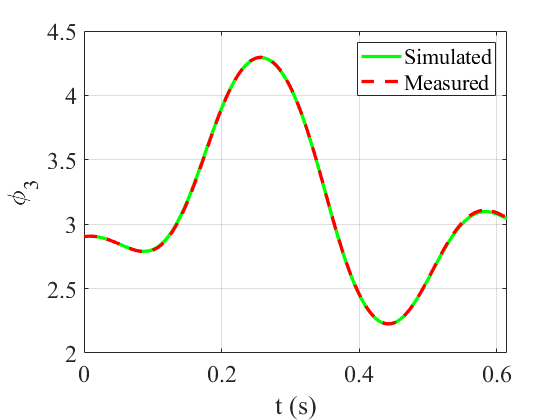

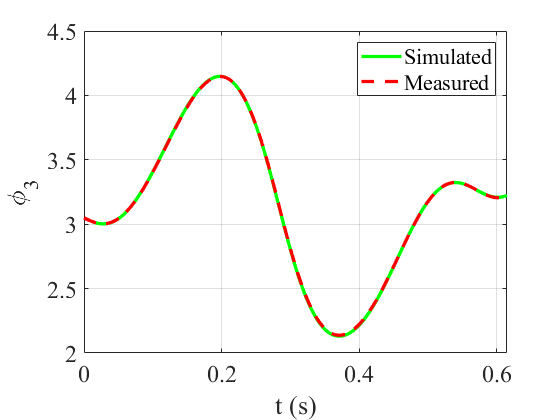

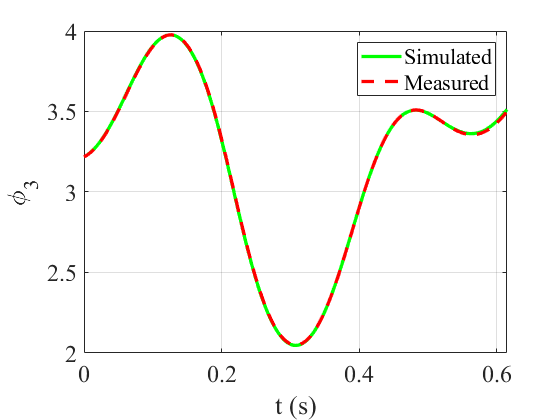

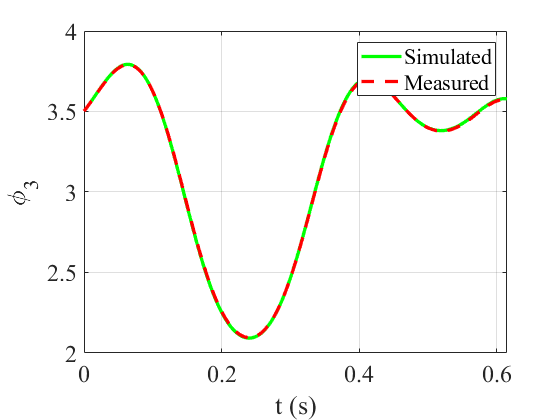

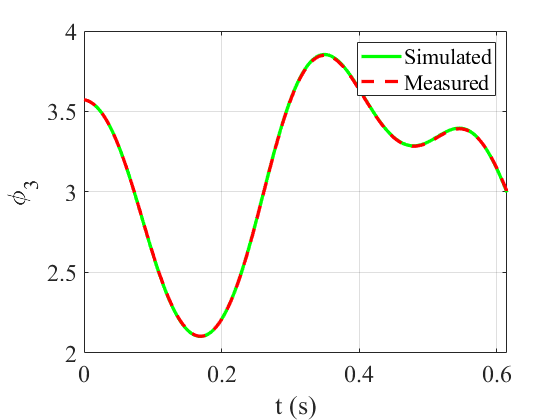

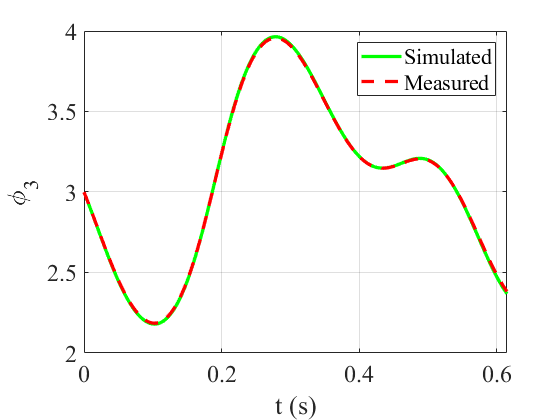

close all
for i=1:length(Y_id)
    figure(i)
    plot(0:dt:length(Y_id{i})*dt-dt,Y_es{i}(3,:),'LineWidth',2.5,'color','green')
    hold on
    plot(0:dt:length(Y_id{i})*dt-dt,Y_id{i}(3,:),'LineWidth',2.5,'LineStyle','--','color','red')
    legend("Simulated","Measured")
    xlabel("t (s)")
    ylabel("\phi_3")
    a = get(gca,'XTickLabel');
    set(gca,'XTickLabel',a,'FontName','Times','fontsize',18)
    grid on
end

# **Now test the estimated parameters on the validation data**

% Now test the parameters using the validation data
Y_es=cell(length(Y_vad),1);

for i=1:length(Y_vad)
    % First determine the simulation time
    tspan=0:dt:length(Y_vad{i})*dt-dt;
    
    % Next, determine the initial condition used for simulation, the first
    % data will be used as initial condition
    y0=Y_vad{i}(:,1);
    
    % Now, run the simulation and simulate the system
    if length(EstimationParameters0)==14
        [~,y_es]=ode89(@(t,y)TriplePendulumODE_Mounted(t,y,EstimatedParameters(1),EstimatedParameters(2),EstimatedParameters(3),...
            EstimatedParameters(4),EstimatedParameters(5),EstimatedParameters(6),...
            EstimatedParameters(7),EstimatedParameters(8),...
            EstimatedParameters(9),EstimatedParameters(10),EstimatedParameters(11),...
            EstimatedParameters(12),EstimatedParameters(13),EstimatedParameters(14),...
            EstimatedParameters(15)),tspan,y0);
    else
        [~,y_es]=ode89(@(t,y)TriplePendulumODE_Mounted(t,y,EstimatedParameters(1),EstimatedParameters(2),EstimatedParameters(3),...
            EstimatedParameters(4),EstimatedParameters(5),EstimatedParameters(6),...
            EstimatedParameters(7),EstimatedParameters(8),...
            EstimatedParameters(9),EstimatedParameters(10),EstimatedParameters(11),...
            EstimatedParameters(12),EstimatedParameters(13),EstimatedParameters(14),...
            9.8083),tspan,y0);
    end
    
    % Now store the simulated data into an array
    Y_es{i}=y_es';
    
    % Now calculate the difference (l2 norm) of the simualted data and measrued data
    l2VadNormError=norm(Y_vad{i}-Y_es{i})^2
end

l2VadNormError = 2.5419

l2VadNormError = 2.3708

l2VadNormError = 2.3759

l2VadNormError = 2.5433

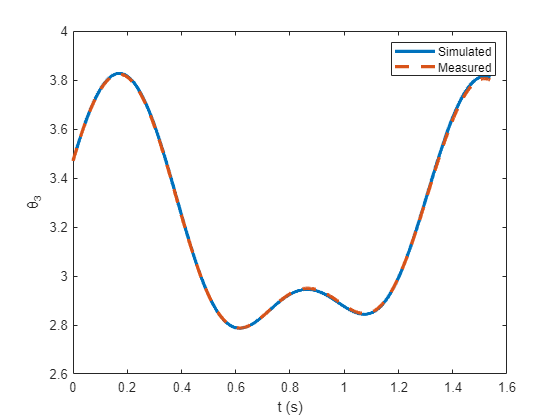

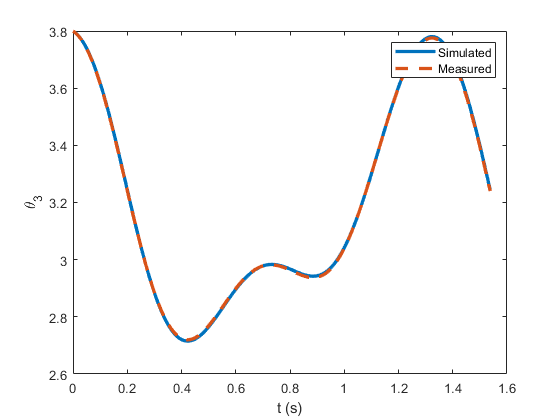

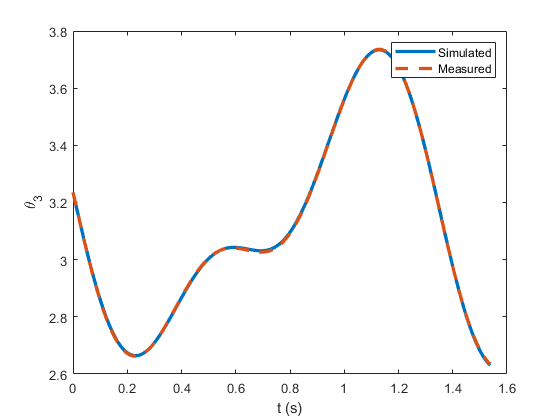

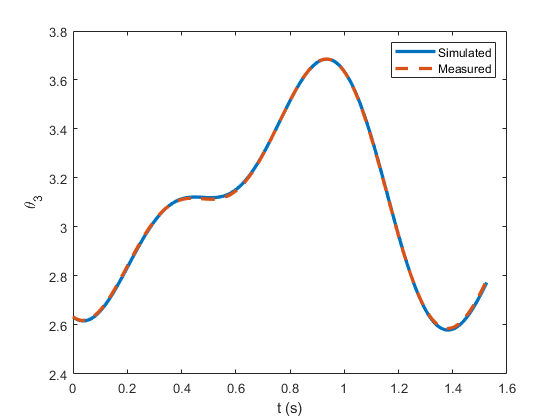

close all
for i=1:length(Y_vad)
    figure(i)
    plot(0:dt:length(Y_vad{i})*dt-dt,Y_es{i}(1,:),'LineWidth',2.5)
    hold on
    plot(0:dt:length(Y_vad{i})*dt-dt,Y_vad{i}(1,:),'LineWidth',2.5,'LineStyle','--')
    legend("Simulated","Measured")
    xlabel("t (s)")
    ylabel("\theta_1")
end

for i=1:length(Y_vad)
    figure(length(Y_vad)+i)
    plot(0:dt:length(Y_vad{i})*dt-dt,Y_es{i}(2,:),'LineWidth',2.5)
    hold on
    plot(0:dt:length(Y_vad{i})*dt-dt,Y_vad{i}(2,:),'LineWidth',2.5,'LineStyle','--')
    legend("Simulated","Measured")
    xlabel("t (s)")
    ylabel("\theta_2")
end
close all
for i=1:length(Y_vad)
    figure(i)
    plot(0:dt:length(Y_vad{i})*dt-dt,Y_es{i}(3,:),'LineWidth',2.5)
    hold on
    plot(0:dt:length(Y_vad{i})*dt-dt,Y_vad{i}(3,:),'LineWidth',2.5,'LineStyle','--')
    legend("Simulated","Measured")
    xlabel("t (s)")
    ylabel("\theta_3")
end